setDir = fullfile('./cutlery');
imds = imageDatastore(setDir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Bag of features
bag = bagOfFeatures(imds, 'VocabularySize', 500, 'PointSelection', 'Detector', 'Verbose', false);

% Classifier training
classifier = trainImageCategoryClassifier(imds, bag);

Training an image category classifier for 5 categories.
--------------------------------------------------------
* Category 1: bread_knife
* Category 2: fork
* Category 3: ladle
* Category 4: spatula
* Category 5: spoon

* Encoding features for 223 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.




% Split the dataset into 80% for training and 20% for testingnImds, testImds] = splitEachLabel(imds, 0.8, 'randomized');
[trainImds, testImds] = splitEachLabel(imds, 0.8, 'randomized');

% Evaluate the classifier on the test image datastore
confMatrix = evaluate(classifier, testImds);

Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: bread_knife
* Category 2: fork
* Category 3: ladle
* Category 4: spatula
* Category 5: spoon

* Evaluating 46 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                   PREDICTED
KNOWN          | bread_knife   fork   ladle   spatula   spoon   
----------------------------------------------------------------
bread_knife    | 1.00          0.00   0.00    0.00      0.00    
fork           | 0.08          0.83   0.00    0.00      0.08    
ladle          | 0.09          0.00   0.82    0.00      0.09    
spatula        | 0.00          0.00   0.00    1.00      0.00    
spoon          | 0.00          0.00   0.00    0.00      1.00    

* Average Accuracy is 0.93.



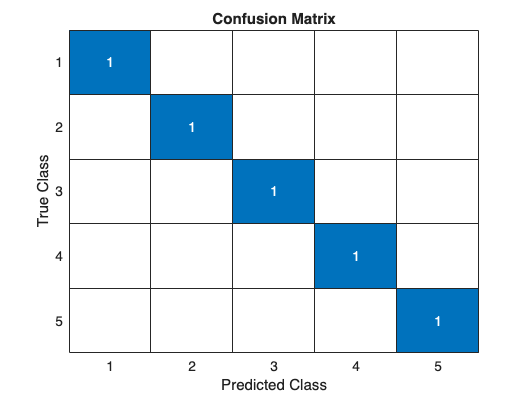


% Convert confusion matrix to integer values
confMatrix = round(confMatrix);

% Display a visual confusion matrix to review the classifier's performance visually.
figure;
confusionchart(confMatrix);
title('Confusion Matrix');


% Class-specific accuracy from the confusion matrix
classSpecificAccuracy = diag(confMatrix) ./ sum(confMatrix, 2);
disp('Class Specific Accuracy:');

Class Specific Accuracy:


disp(array2table(classSpecificAccuracy, 'RowNames', classifier.Labels));

                   classSpecificAccuracy
                   _____________________

    bread_knife              1          
    fork                     1          
    ladle                    1          
    spatula                  1          
    spoon                    1          




% Overall accuracy
overallAccuracy = mean(diag(confMatrix));
fprintf('Overall accuracy: %.2f%%\n', overallAccuracy * 100);

Overall accuracy: 100.00%
